# **Efficient Frontier for 3 Assets**

The 72 monthly returns for 3 assets is saved in the file '3AssetsData.mat'. The monthly returns of 3 assets ('SPY', 'GOVT', 'EEMV') between jan 2014 and december 2019 is used. The monthly returns are calculated using adjusted colsing price of the assets on the first and last trading day of each month. Loading the file '3AssetsData' loads the variale 'returns' in the current workspace.

load('3AssetsData')

# Computation of parameters

% arithmatic average of each stock
avg_return = mean(returns)

% geometric expected return of each stock
GM_return = nthroot(prod(returns + 1), 72) - 1


avg_return =     0.0095    0.0025    0.0030


% covariance between assets
cov_mat = cov(returns,1)


GM_return =     0.0090    0.0024    0.0025


% standard deviation of assets
stddev = sqrt(diag(cov_mat)')

# Mean-Variance Optimization 

## Minimum variance point

H = cov_mat;

cov_mat =     0.0010   -0.0001    0.0006
   -0.0001    0.0001    0.0000
    0.0006    0.0000    0.0010


c = [0 0 0]';
A = []; % find minimum variance point using no contraint for return
b = [];

stddev =     0.0322    0.0094    0.0317


Aeq = [1 1 1];
beq = [1];
ub = [inf; inf; inf;];
lb = [-inf; -inf; -inf;]; %with short selling
lb_without = [0; 0; 0;]; %without short selling
% turn off the exit message
x0 = [];
options =  optimoptions(@quadprog,'Display','off');

#### With short selling

% minimum variance point with short selling
[w_ss, fval_min_ss] = quadprog(H, c, A, b, Aeq, beq, lb, ub, x0,options)

% portfolio return at min variance point with short selling
r_ss = GM_return * w_ss

#### Without short selling

% minimum variance point without short selling
[w_no_ss, fval_min_no_ss] = quadprog(H, c, A, b, Aeq, beq, lb_without, ub, x0,options)

% portfolio return at min variance point without short selling
r_no_ss = GM_return * w_no_ss

## Vary portfolio return (goal) to get points on efficient frontiers

A = -GM_return;

w_ss =     0.1675
    0.8810
   -0.0485


fval_min_ss = 3.1123e-05

#### with short selling

weights_ss = [];

r_ss = 0.0035

fvals_ss = [];
r_goal_ss = 0.0035:0.0005:0.010;
% portfolio returns
r_goal_ss = [r_ss r_goal_ss]

w_no_ss =     0.1378
    0.8622
    0.0000


fval_min_no_ss = 3.1819e-05

for b = r_goal_ss
    [w_min, fval_min] = quadprog(H, c, A, -b, Aeq, beq, lb, ub, x0,options);  
    weights_ss = [weights_ss, w_min];

r_no_ss = 0.0033

    fvals_ss(end + 1) = fval_min;
end
% portfolio standard deviations
volatility_ss = sqrt(2*fvals_ss)

#### without short selling

weights_no_ss = [];
fvals_no_ss = [];
r_goal_no_ss = 0.0035:0.0005:0.0085;
% portfolio returns
r_goal_no_ss = [r_no_ss r_goal_no_ss]

r_goal_ss =     0.0035    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100


for b = r_goal_no_ss
    [w_min, fval_min] = quadprog(H, c, A, -b, Aeq, beq, lb_without, ub, x0,options);  
    weights_no_ss = [weights_no_ss, w_min];
    fvals_no_ss(end + 1) = fval_min;
end
% portfolio standard deviations
volatility_no_ss = sqrt(2*fvals_no_ss)

volatility_ss =     0.0079    0.0079    0.0081    0.0089    0.0100    0.0114    0.0130    0.0146    0.0164    0.0183    0.0201    0.0221    0.0240    0.0260    0.0279


# Plot efficient frontier

%plot efficient frontier with short selling and without short selling
figure
plot(volatility_ss, r_goal_ss,'r-*')
hold on 
plot(volatility_no_ss, r_goal_no_ss, 'k-o' )
hold off

r_goal_no_ss =     0.0033    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085


volatility_no_ss =     0.0080    0.0080    0.0088    0.0103    0.0122    0.0144    0.0168    0.0192    0.0218    0.0244    0.0270    0.0296


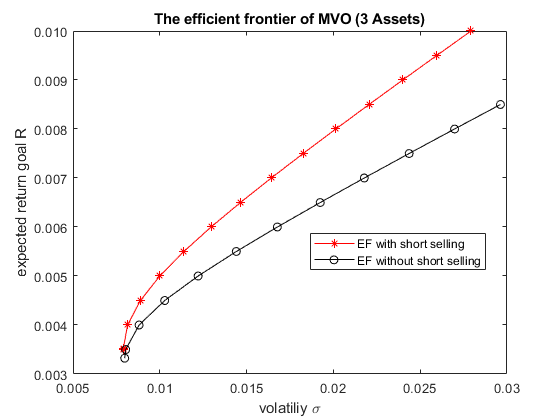

legend({'EF with short selling', 'EF without short selling'}, 'Location','best')
title('The efficient frontier of MVO (3 Assets)')
xlabel('volatiliy \sigma')
ylabel('expected return goal R')
ytickformat('%.3f')
ax = gca;
ax.YAxis.Exponent = 0;